## System Paramters

param_dict = read_system_dict();

Test params

param_dict.state_space.around_T_0.A

ans =    -1.5222         0   -0.0186
         0   -0.0625   -0.0000
   21.0414    0.0000    0.1990


param_dict.state_space.around_T_0.b

ans =          0
         0
    0.0625


param_dict.state_space.around_U.b

ans = 1.0e-04 *

         0
         0
   -0.3673


## Problem 5

p5_sol = p_5();

System around $T_0$

p5_sol.around_T_0.poles

ans =    -1.2532
   -0.0700
   -0.0625


p5_sol.around_T_0.zeros

ans =    -1.5222
   -0.0625


p5_sol.around_T_0.k

ans = 1.0840

p5_sol.around_T_0.eigen_values

ans =    -1.2532
   -0.0700
   -0.0625


System around U

p5_sol.around_U.poles

ans =    -1.2532
   -0.0700
   -0.0625


p5_sol.around_U.zeros

ans =    -1.5222
   -0.0625


p5_sol.around_U.k

ans = -6.3713e-04

p5_sol.around_U.eigen_values

ans =    -1.2532
   -0.0700
   -0.0625


All poles and eigenvlaues are negative. The system is asymptotically and BIBO stable.

## Problem 6

p6_sol = p_6();

% figure
% plot(p6_sol.minus_5K_step.t, p6_sol.minus_5K_step.y, p6_sol.plus_5K_step.t, p6_sol.plus_5K_step.y, p6_sol.plus_10K_step.t, p6_sol.plus_10K_step.y, p6_sol.plus_20K_step.t, p6_sol.plus_20K_step.y)
% grid on
% legend("-5K Step", "+5K Step", "+10K Step", "+20K Step")
% figure
% plot(p6_sol.plus_10K_step.t, p6_sol.plus_10K_step.y+param_dict.steady_state.T, p6_sol.non_linear_10K_step.t, p6_sol.non_linear_10K_step.y(:,3))
% grid on
% legend("Linear", "Non-Linear")

## Problem 7

approximate_T_s = 10.83;
one_tau = approximate_T_s * 0.632;
low_coord = [15.15 7.049];
up_coord = [14.14 6.772];

interp_t = (low_coord(1) - up_coord(1)) / (low_coord(2) - up_coord(2)) * (one_tau - low_coord(2)) + low_coord(1);

k_graph = interp_t/10

k_graph = 1.4405

## Problem 8

## Problem 9

## Problem 10

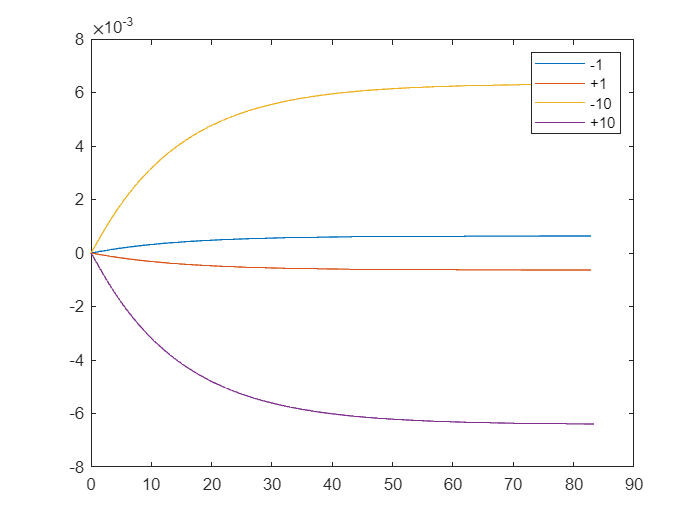

p10_sol = p_10();

plot( ...
    p10_sol.k_c_plots.set_point.minus_1.t, p10_sol.k_c_plots.set_point.minus_1.y, ...
    p10_sol.k_c_plots.set_point.plus_1.t, p10_sol.k_c_plots.set_point.plus_1.y, ...
    p10_sol.k_c_plots.set_point.minus_10.t, p10_sol.k_c_plots.set_point.minus_10.y, ...
    p10_sol.k_c_plots.set_point.plus_10.t, p10_sol.k_c_plots.set_point.plus_10.y...
    )
legend("-1", "+1", "-10", "+10")

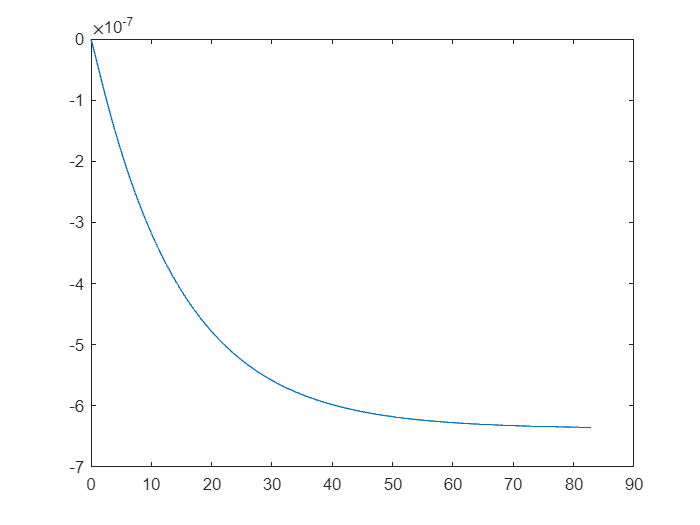

plot(p10_sol.optimal_k_c.t, p10_sol.optimal_k_c.y)

## Problem 11

## Problem 12

Solutions saving

% sols = {};
% sols.p_5 = p5_sol;
% sols.p_6 = p6_sol;
% sols.p_10 = p10_sol;
% 
% fid=fopen("solutions.json", 'w');
% fprintf(fid, jsonencode(sols, PrettyPrint=true)); 
% fclose('all'); 